`Erfan Panahi   810198369`

## Communication Systems I

# Computer Assignement 2

# ` Part 1.`

`Definition of `$x_m \left(t\right)$`:`

clear;
fs = 2000;
fc = 250;
t0 = 0.15;
t = 0:1/fs:t0;
Ac = 1;
mu = 0.85;
xm(1:t0*fs/3)=1;
xm(t0*fs/3+1:2*t0*fs/3)=-2;
xm(2*t0*fs/3+1:t0*fs+1)=0;

$x_c \left(t\right)$`:`

xm = xm/max(abs(xm));
xc = AMmod(xm,Ac,mu,fc,t);
plot(t,xc);

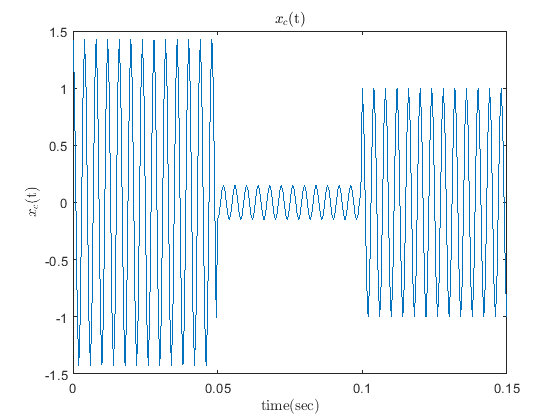

title('$x_c$(t)','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$x_c$(t)','Interpreter','latex');

$X_m \left(f\right)$`:`

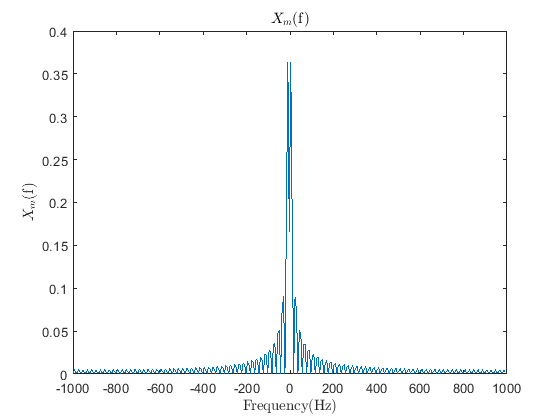

f=-fs/2:fs/length(t):(fs-1)/2;
Xmf=fftshift(fft(xm))/length(xm);
plot(f,abs(Xmf));
title('$X_m$(f)','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('$X_m$(f)','Interpreter','latex');

$X_c \left(f\right)$`:`

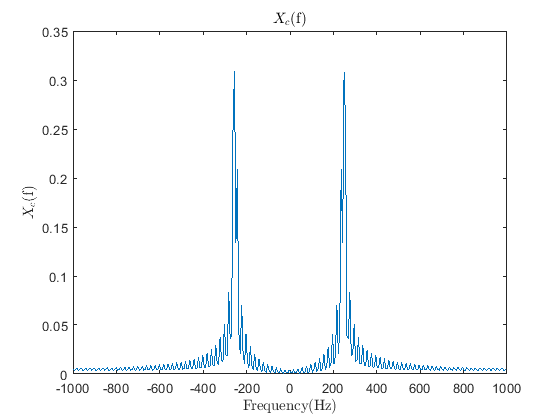

Xcf=fftshift(fft(xc))/length(xc);
plot(f,abs(Xcf));
title('$X_c$(f)','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('$X_c$(f)','Interpreter','latex');

`Power of` $x_c \left(t\right)$`:`

Sx = sum(xm.^2)/(t0*fs);
ST = Ac^2/2*(1+mu^2*Sx)

ST = 0.6505

`Modulation Efficiency: `


$$\eta =\frac{S_{\mathrm{sb}} }{S_T }=\frac{A_c^2 }{2}\frac{{\mu^2 S}_x }{S_T }=\frac{{\mu^2 S}_x }{1+{\mu^2 S}_x }$$


n = mu^2*Sx / (1 + mu^2*Sx)

n = 0.2314

$x_c \left(t\right)$ `using` `ammod:`

`y = ammod(x,Fc,Fs)`` returns an amplitude modulated (AM) signal y, given the input message signal x, where the carrier signal has frequency Fc. The carrier signal and x have a sampling frequency Fs. The modulated signal has zero initial phase and zero carrier amplitude, so the result is suppressed-carrier modulation.`

`y = ammod(x,Fc,Fs,0,carramp)`` performs transmitted-carrier modulation instead of suppressed-carrier modulation where carramp is the carrier amplitude of the modulated signal.`

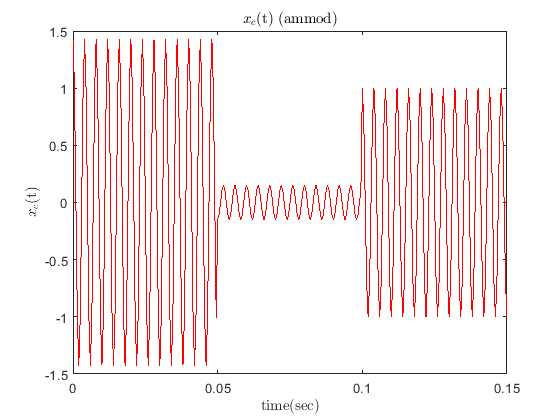

xc2=ammod(mu*Ac*xm,fc,fs,0,Ac);
plot(t,xc2,'r');
title('$x_c$(t) (ammod)','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$x_c$(t)','Interpreter','latex');

# `Part 2.`

`Definition of `$m\left(t\right)$`:`

clear;
fs = 600;
t = -5:1/fs:5;
m = sinc(30*t).^2;

$m\left(t\right)$ `time-domain:`

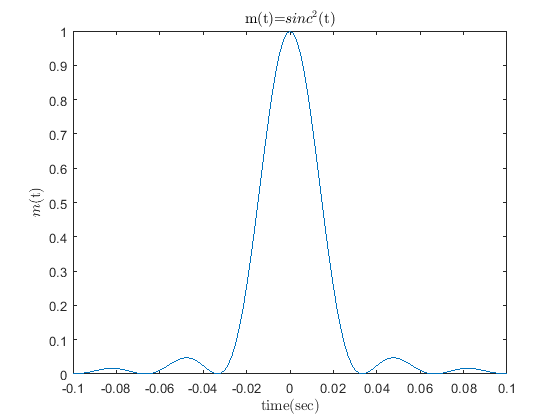

plot(t,m);
xlim([-0.1 0.1]);
title('m(t)=$sinc^2$(t)','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$m$(t)','Interpreter','latex');

$M\left(f\right)$ `Spectrum:`

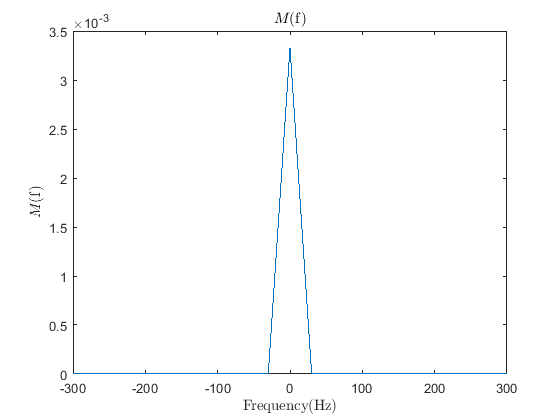

f=-fs/2:fs/length(t):fs/2-1/length(t);
Mf=fftshift(fft(m))/length(m);
plot(f,abs(real(Mf)));
title('$M$(f)','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('$M$(f)','Interpreter','latex');

`DSB modulation of` $m\left(t\right)$ `:`

    
$$f_c =\left\lbrace 50,200\right\rbrace$$


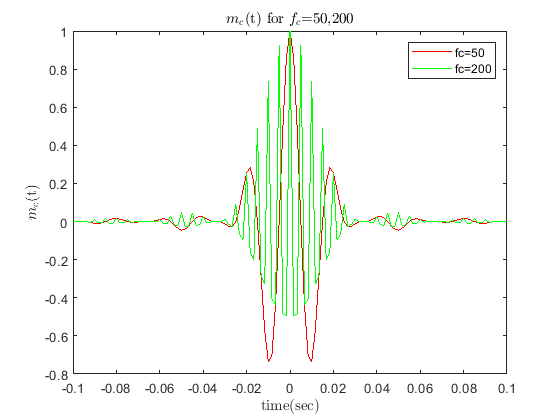

Ac = 1;
fc1 = 50;
fc2 = 200;
mc1 = DSBmod(m,Ac,fc1,t);
mc2 = DSBmod(m,Ac,fc2,t);
plot(t,mc1,'r',t,mc2,'g');
xlim([-0.1 0.1]);
legend('fc=50','fc=200');
title('$m_c$(t) for $f_c$={50,200}','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$m_c$(t)','Interpreter','latex');

        
$$f_c =\left\lbrace 600,1200\right\rbrace$$


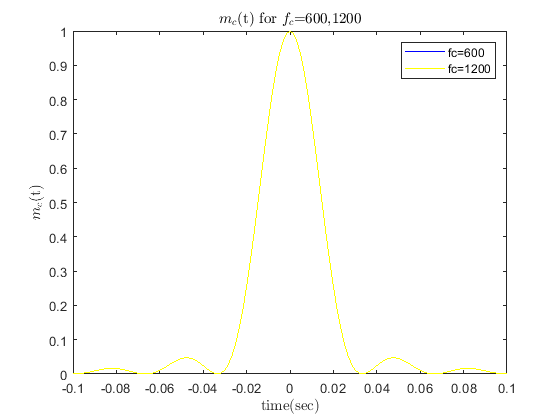

fc3 = 600;
fc4 = 1200;
mc3 = DSBmod(m,Ac,fc3,t);
mc4 = DSBmod(m,Ac,fc4,t);
plot(t,mc3,'b',t,mc4,'y');
xlim([-0.1 0.1]);
legend('fc=600','fc=1200');
title('$m_c$(t) for $f_c$={600,1200}','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$m_c$(t)','Interpreter','latex');

`we define t as `$t=0,\pm \frac{1}{f_s },\pm \frac{2}{f_s },\ldotp \ldotp =\frac{k}{f_s }$ $\longrightarrow \mathrm{cos}\left(2\pi f_c t\right)=\mathrm{cos}\left(2\pi k\right)=1$ 

`so `$m_s \left(t\right)=m\left(t\right)$ `if `$f_c =m\ldotp f_s$ `. `

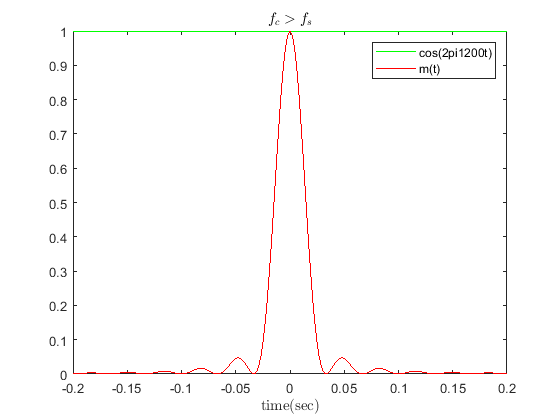

plot(t,cos(2*pi*fc4*t),'g',t,m,'r');
xlim([-0.2 0.2]);
legend('cos(2pi1200t)','m(t)');
title('$f_c>f_s$','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');

`DSB modulation of` $m\left(t\right)$ `for` $f_c =100\mathrm{Hz}$ `:`

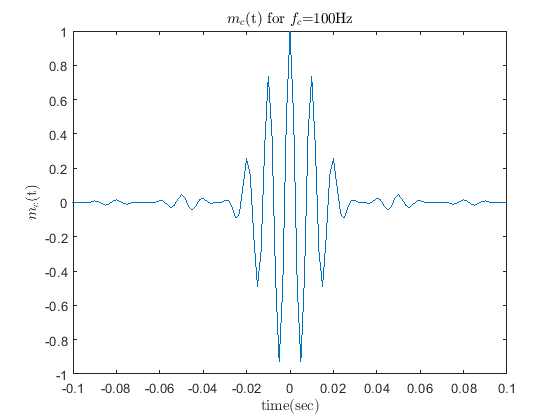

fc = 100;
mc = DSBmod(m,Ac,fc,t);
plot(t,mc);
xlim([-0.1 0.1]);
title('$m_c$(t) for $f_c$=100Hz','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$m_c$(t)','Interpreter','latex');

$M_c \left(f\right)$`:`

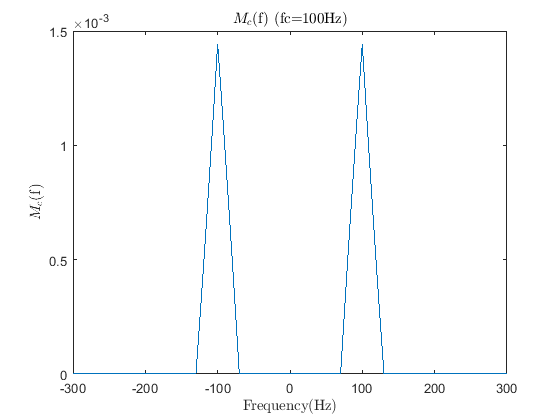

Mcf=fftshift(fft(mc))/length(mc);
plot(f,abs(real(Mcf)));
title('$M_c$(f) (fc=100Hz)','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('$M_c$(f)','Interpreter','latex');

`DSB demodulation of` $M_c \left(f\right)$ `:`

[y,z] = DSBdemod(mc,Ac,fc,t);

$y\left(t\right)$` time-domain:`

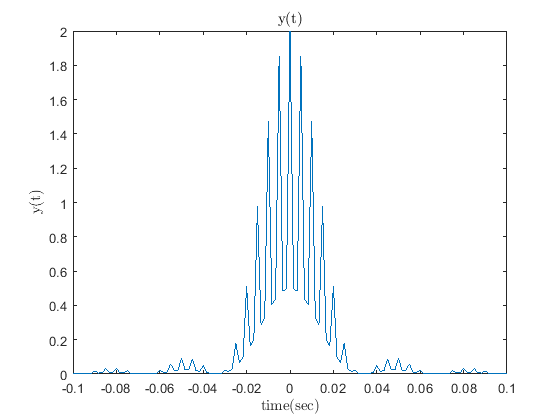

plot(t,y);
xlim([-0.1 0.1]);
title('y(t)','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('y(t)','Interpreter','latex');

$z\left(t\right)$` time-domain:`

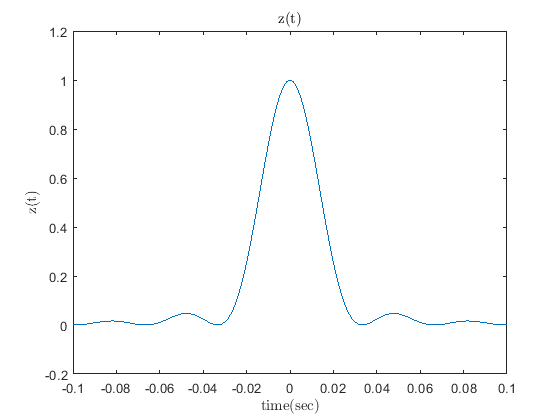

plot(t,z);
xlim([-0.1 0.1]);
title('z(t)','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('z(t)','Interpreter','latex');

$Y\left(f\right)$`:`

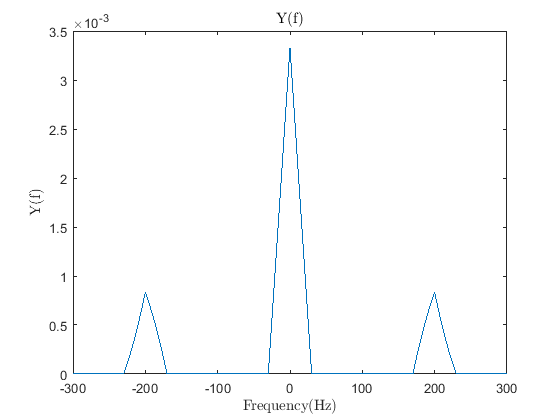

Yf=fftshift(fft(y))/length(y);
plot(f,abs(real(Yf)));
title('Y(f)','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('Y(f)','Interpreter','latex');

$Y\left(f\right)$`:`

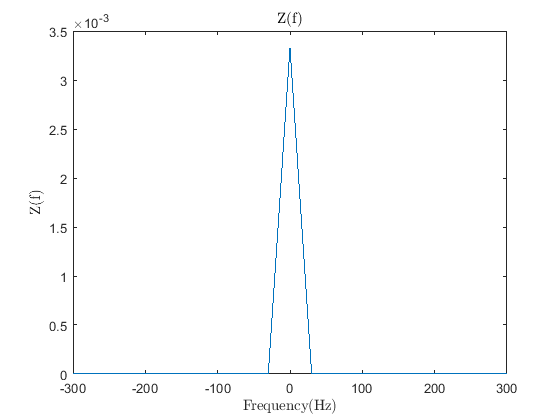

Zf=fftshift(fft(z))/length(z);
plot(f,abs(real(Zf)));
title('Z(f)','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('Z(f)','Interpreter','latex');

`Comparing:`

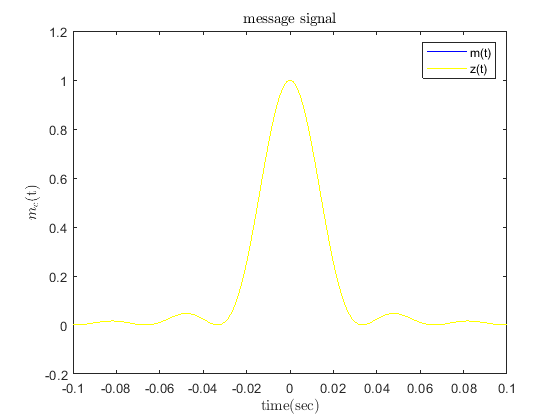

plot(t,m,'b',t,z,'y');
xlim([-0.1 0.1]);
legend('m(t)','z(t)');
title('message signal','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$m_c$(t)','Interpreter','latex');

`Mean squared error:`

MSEzm = immse(z,m)

MSEzm = 6.9718e-11

`MSE plotting for `$f_c =\left\lbrack -500,500\right\rbrack$

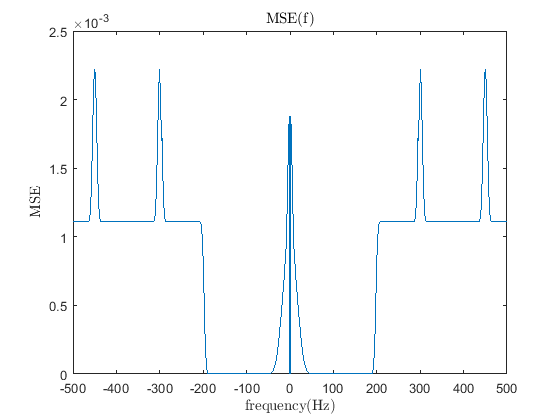

warning('off','all');
f_er = -500:1:500;
MSEf(501) = 0;
for i = f_er 
    if i ~= 0
        mc_fc = DSBmod(m,Ac,i,t);
        [m1,z1] = DSBdemod(mc_fc,Ac,i,t);
        MSEf(i+501) = immse(z1,m);
    end
end
plot(f_er,MSEf);
title('MSE(f)','Interpreter','latex');
xlabel('frequency(Hz)','Interpreter','latex');
ylabel('MSE','Interpreter','latex');

`DSB modulation` `using` `ammod:`

mc_=ammod(Ac*m,fc,fs);

    
$$m_c \left(t\right):$$


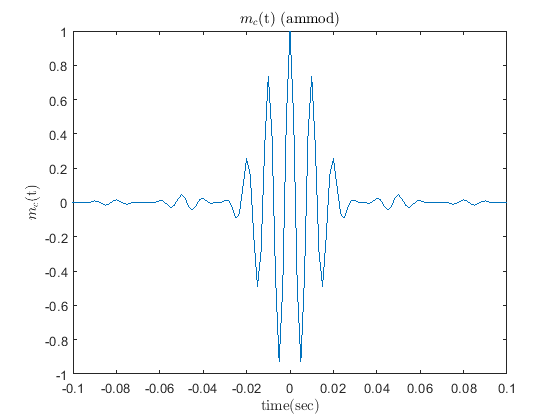

plot(t,mc_);
xlim([-0.1 0.1]);
title('$m_c$(t) (ammod)','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$m_c$(t)','Interpreter','latex');

    
$$M_c \left(f\right):$$


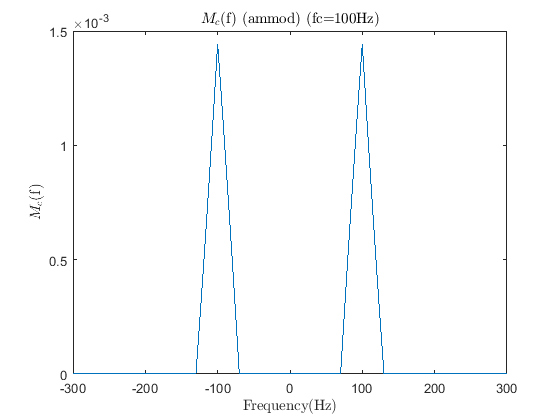

Mcf_=fftshift(fft(mc_))/length(mc_);
plot(f,abs(real(Mcf_)));
title('$M_c$(f) (ammod) (fc=100Hz)','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('$M_c$(f)','Interpreter','latex');

`DSB demodulation` `using` `amdemod:`

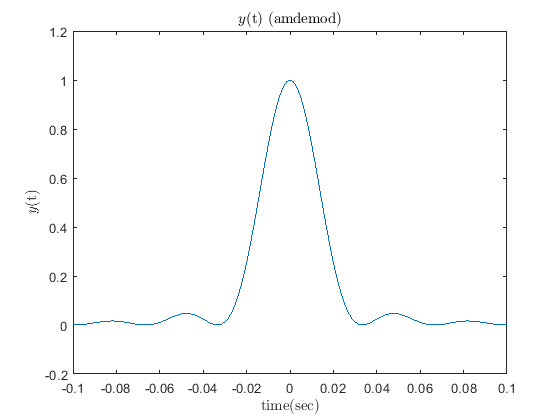

y_ = amdemod(Ac*mc,fc,fs);
plot(t,y_);
xlim([-0.1 0.1]);
title('$y$(t) (amdemod)','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$y$(t)','Interpreter','latex');

`Mean squared error:`

MSEy_m = immse(y_,m)

MSEy_m = 2.8463e-12

`SSB modulation` `using` `ssbmod:`

mc_lssb=ssbmod(Ac*m,fc,fs);
mc_ussb=ssbmod(Ac*m,fc,fs,0,'upper');

      
$$M_c \left(f\right)\;L\textrm{SSB}:$$


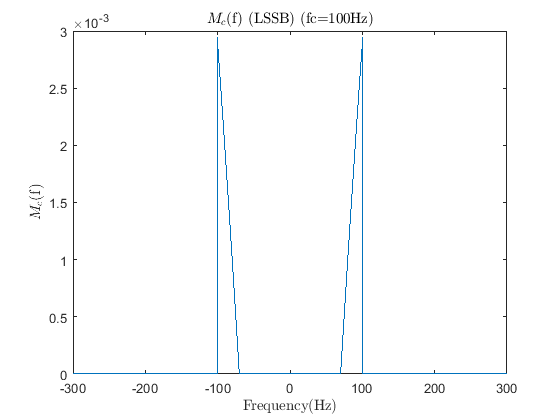

Mcf_lssb=fftshift(fft(mc_lssb))/length(mc_lssb);
plot(f,abs(real(Mcf_lssb)));
title('$M_c$(f) (LSSB) (fc=100Hz)','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('$M_c$(f)','Interpreter','latex');

     
$$M_c \left(f\right)\;\mathrm{USSB}:$$


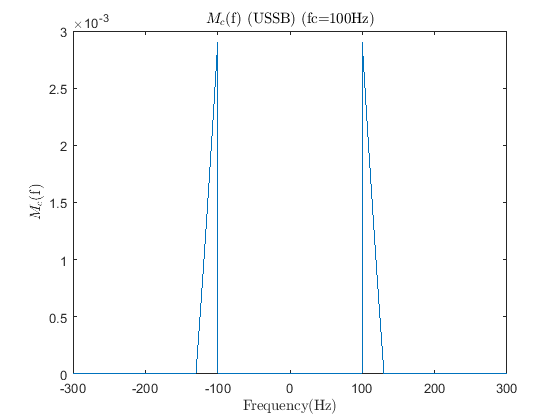

Mcf_ussb=fftshift(fft(mc_ussb))/length(mc_ussb);
plot(f,abs(real(Mcf_ussb)));
title('$M_c$(f) (USSB) (fc=100Hz)','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('$M_c$(f)','Interpreter','latex');

# ` Part 3.`

`Definition of `$m\left(t\right)$`:`

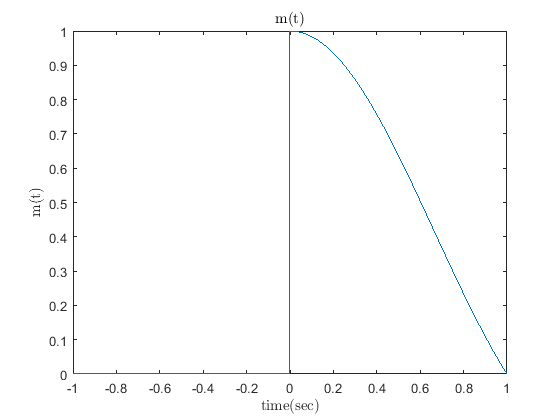

clear;
fs = 500;
t = -1:1/fs:1;
m(fs+1:2*fs+1) = sinc(t(fs+1:2*fs+1));
plot(t,m);
title('m(t)','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('m(t)','Interpreter','latex');

$\hat{m} \left(t\right)$`:`

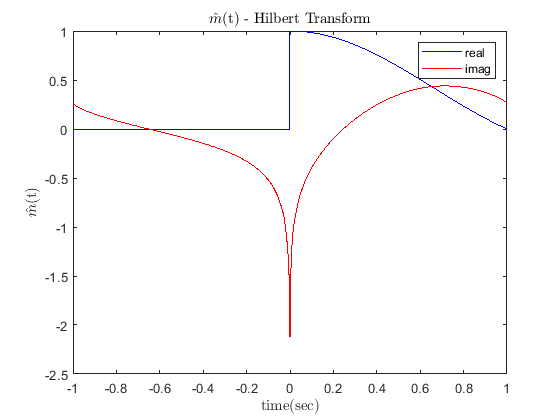

m_hat = hilbert(m);
plot(t,real(m_hat),'b',t,imag(m_hat),'r');
legend('real','imag');
title('$\hat{m}$(t) - Hilbert Transform','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$\hat{m}$(t)','Interpreter','latex');

`DSB modulation of `$m\left(t\right)$`:`

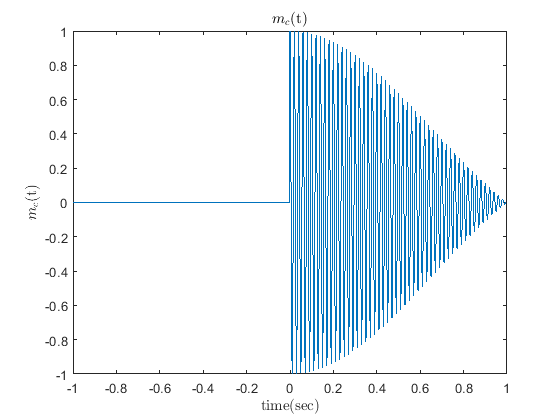

Ac=1;
fc = 50;
mc=ammod(Ac*m,fc,fs);
plot(t,mc);
title('$m_c$(t)','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$m_c$(t)','Interpreter','latex');

`Envelope Detector:`

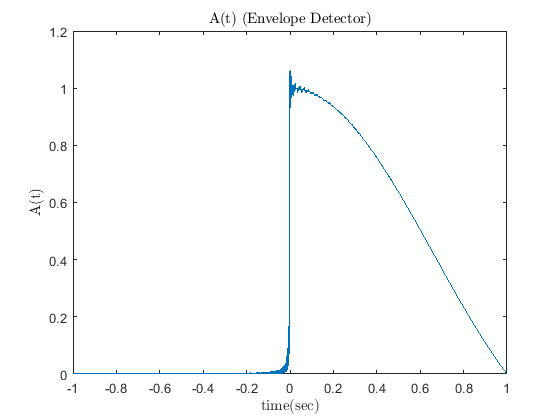

At = EnvDet(Ac,mc);
plot(t,real(At));
title('A(t) (Envelope Detector)','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('A(t)','Interpreter','latex');

`Mean squared error:`

MSE_Am = immse(At,m)

MSE_Am = 4.0978e-04

`Using synchronous demodulation:`

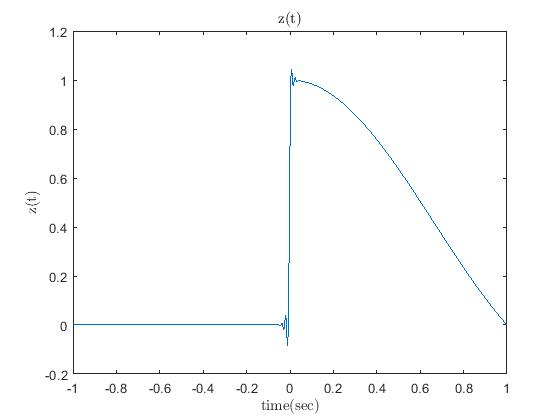

[y,z] = DSBdemod(mc,Ac,fc,t);
plot(t,z);
title('z(t)','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('z(t)','Interpreter','latex');

`Mean squared error:`

MSE_zm = immse(z,m)

MSE_zm = 4.9666e-04

# `Functions:`

`Function for AM Modulation:`

function [xc] = AMmod (xm,Ac,mu,fc,t)
    xc = Ac*(1+mu*xm).*cos(2*pi*fc*t);
end

`Function for DSB Modulation:`

function [xc] = DSBmod (m,Ac,fc,t)
    xc = Ac*m.*cos(2*pi*fc*t);
end

`Function for DSB Demodulation:`

function [s,m] = DSBdemod (mc,Ac,fc,t)
    s = 2*Ac*mc.*cos(2*pi*fc*t);
    m = lowpass(s,abs(fc),600);
end

`Function for Envelope Detector:`

function [At] = EnvDet (Ac,m)
    m_hat = hilbert(m);
    At = Ac*sqrt(m.^2+imag(m_hat).^2);
end